## Gibbs Ringing, Aliasing and Simulation

In MRI, during the Frequency Encode (FE) readout, a gradient is applied, the field strength then varies with position and spins rotate at different speeds depending on their position. The signal received as a function of time (k-sace) is from the whole excited object t and its Fourier Transform gives the amount of 'tissue' at each temporal frequency (position) - i.e. the image. In practice, the time domain continuous signal from the patient is repeatedly sampled as part of the acquisition. This sampling and the Fourier representation are behind wrapping and aliasing effects.

The Gibbs phenominon is usually thought of as what happens when we try to represent a sharp edge by a sum of sines and cosines. The more oscillating signas we add with higher and higer frequencies, the more closely we can approxiate a square wave, but, an overshoot and under shoot, each of 9% remain, no matter how many frequencies are included. Another way of thinking of this is that a continuous k-space signal (which for a sharp edge decays roughly as 1/k) is truncated. Truncation in k-space is multiplication by a rect function, which is equivalent to convolving the true image by the FT of the rect, i.e. convolving with a sinc function. This gives the ripples.

In a sense, both Gibs and aliasing are conseqeunces of not being able to sample indefinitely, 

Unfortuantely, demonstrating and modelling some of these effects on a computer can be misleading because the data in a computer program has to be discretised.

### Truncation

First, take a line profile through a 'phantom' prostate to get a 1D signal.

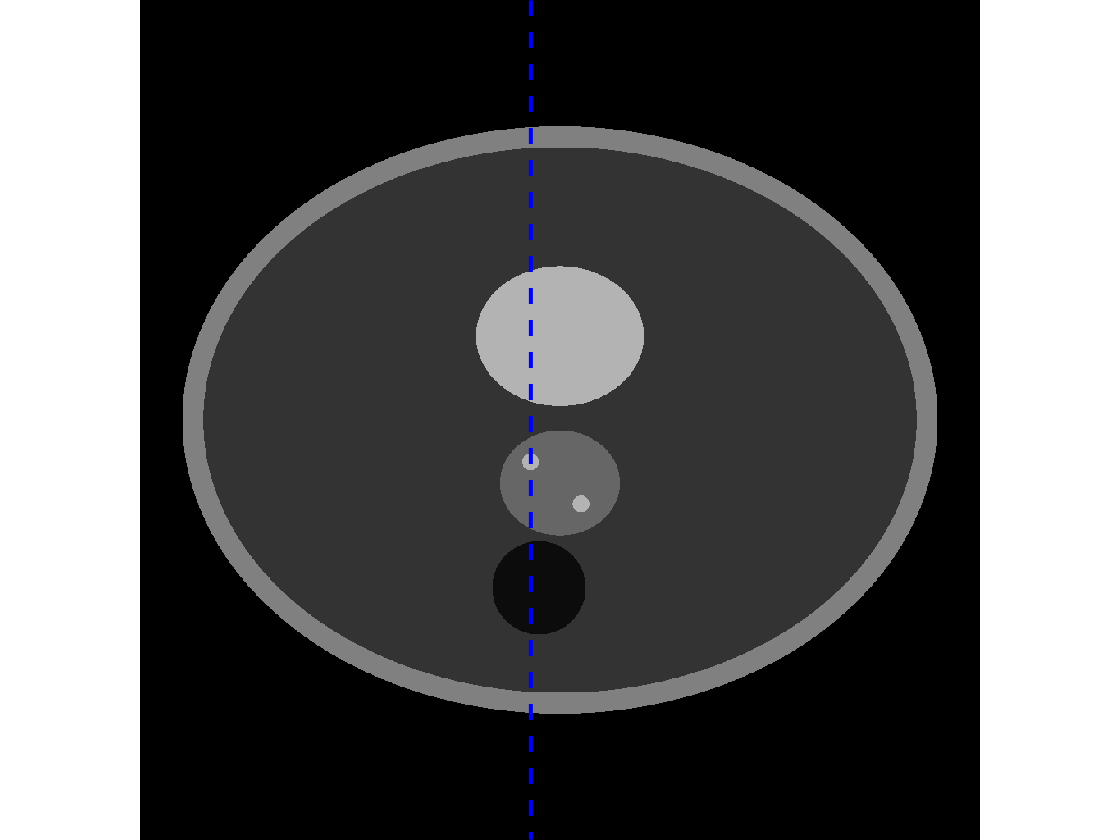

nhr = 1024 ; column = 477 ;
imghr = prostate(nhr) ;
xhr = imghr(:,column) ; % column as a line profile

figure('Name','prostate image')
imshow(imghr), hold on, 
plot([column column],[1 nhr],'b--','LineWidth',2)

This profile has **nhr** (1024) points. Let's create a mask that is zero everywhere exept for the central 128 points and mask the k-space from this profile.

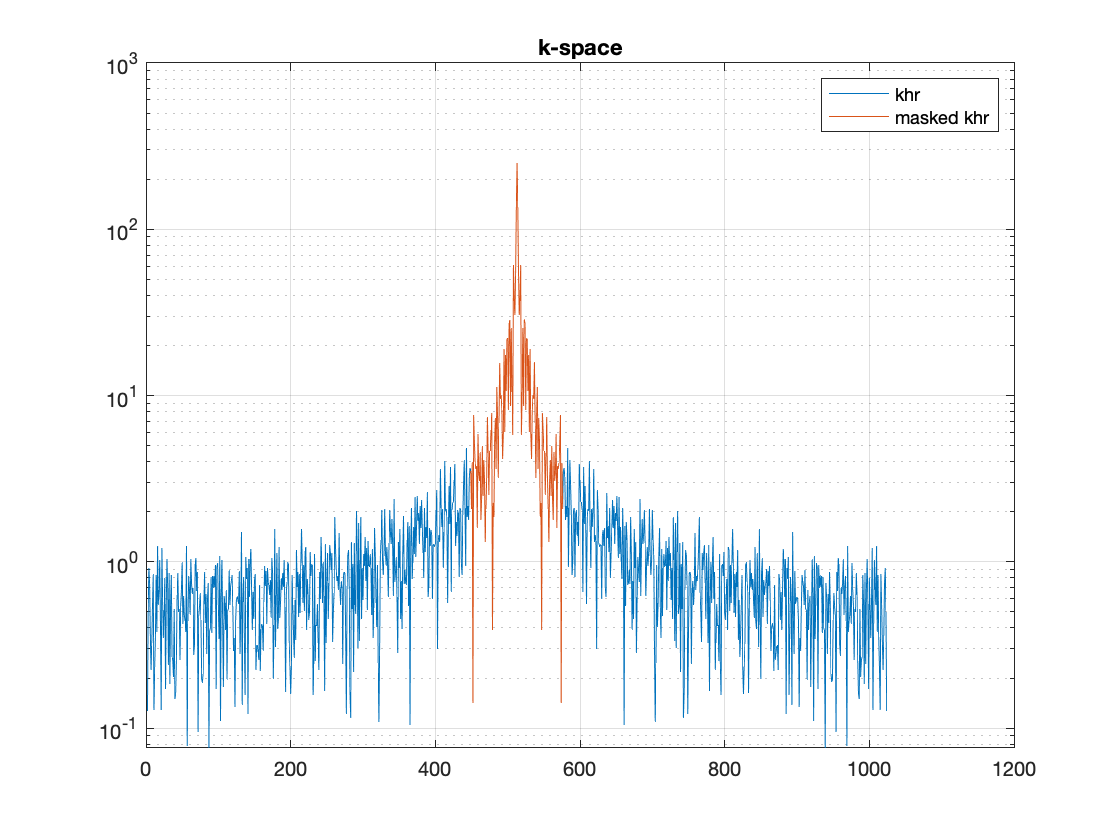

mask = zeros([nhr 1]) ;
dc = sz2DC(nhr) ; % The central index ('DC' or origin) - here 1024/2+1 = 513
mask(dc-64:dc+63) = 1 ; % Set mask to 1 in just the central region

khr = i2k(xhr) ;           % k-space of the profile xhr
khr_masked = khr .* mask ; % masked k-space

figure
semilogy(abs(khr), 'DisplayName','khr'), legend, hold on, grid on
title('k-space')
semilogy(abs(khr_masked), 'DisplayName','masked khr')

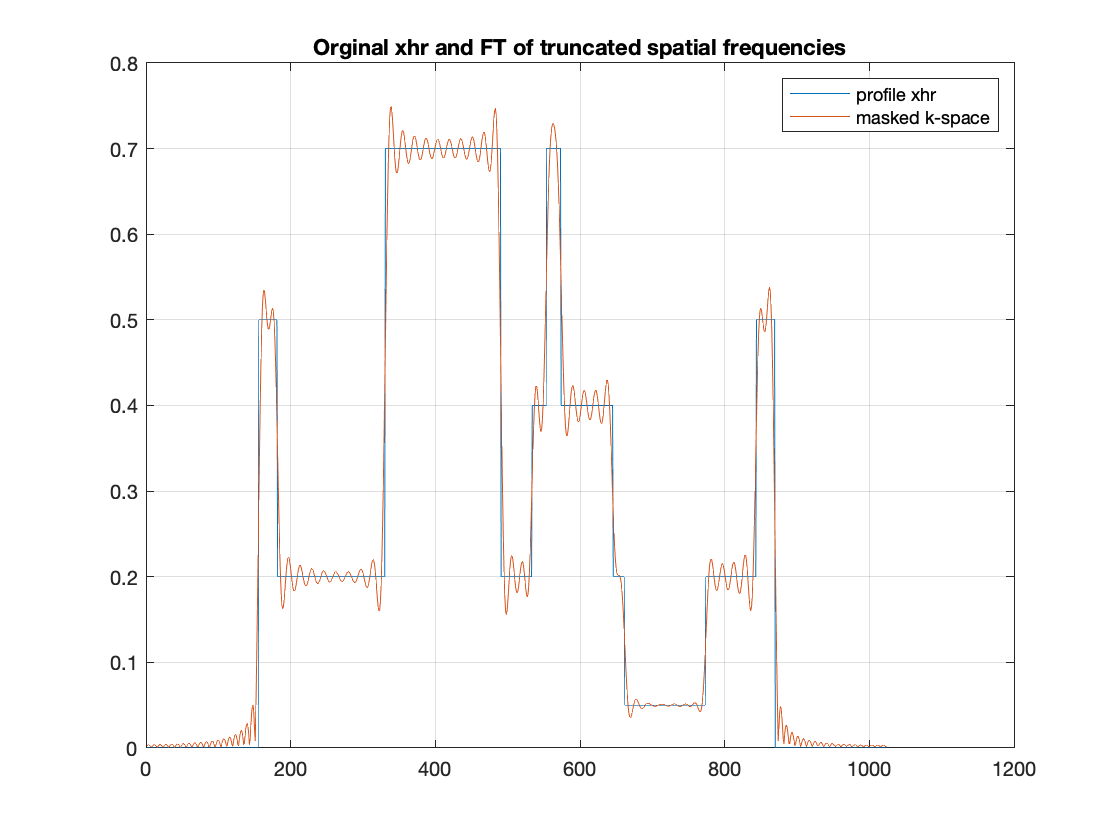

figure('Name','profile')
plot(xhr, 'DisplayName','profile xhr'), legend, hold on, grid on
title('Orginal xhr and FT of truncated spatial frequencies')
plot(abs(k2i(khr_masked)), 'DisplayName','masked k-space')

We see the classic Gibbs ringing in the above.

### Simulation Issues

In the above, we simulated 1024 k-space points, zerod all except the central 128 and then took the Fourier Transform. If instead, we take the central 128 k-space points and Fourier Transform just those, what we get is similar, but not identical (look closely at the ringing)

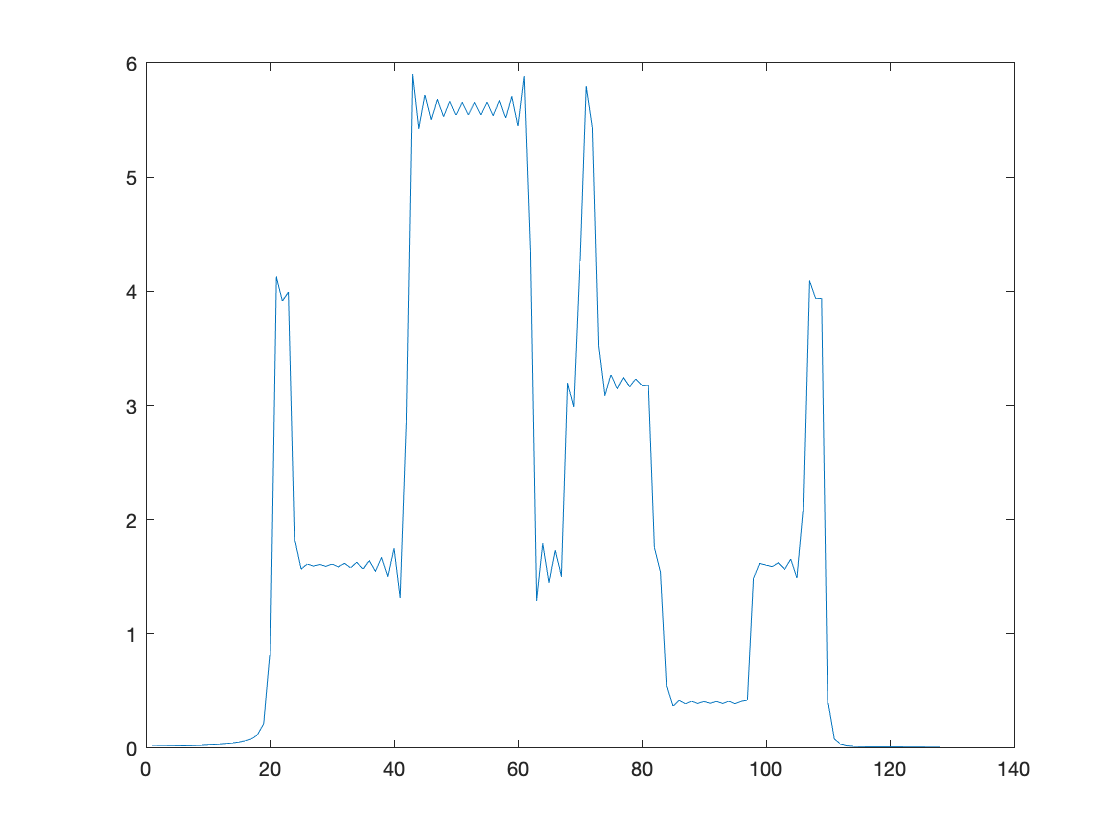

kcent = khr(mask==1) ;
figure
plot(abs(k2i(kcent)))

So which is a more accurate simulation of the acquisition process? At least for a sampked continuous signal, neither is correct because they don't take account of aliasing. Aliasing means the unacquired spatial frequencies fold into those acquired. This is different from the first case above where the 1024 k-space was filtered. This filtering removes high-spatial frequenciies, wheras in aliasing they are folded into the acquired data. 

### Another issue in simulation

Typically, to perform a simulation, we take an image wihtout ringing and FT it to give a simulated, acquired k-space without changing array sizes. If this simulated k-space is then transformed back to the image domain, we will get back the original exactly, without ringing. 

We don't get ringing induced because we just performed a transform and its exact inverse. One point to note is that if we were to convolve the image with the FT of a rect the same size as the simulated k-space, we still do not see ringing. This is because in this particular situation, the image data points fall at the zero crossings of the sinc.

In fact, we can 'reveal' this by applying a phase ramp in k-space to shift the image by a non-integer number of pixels. Here we use a similar phantom but with only 128 points in the profile and for a half pixel shift, see ripples appear.

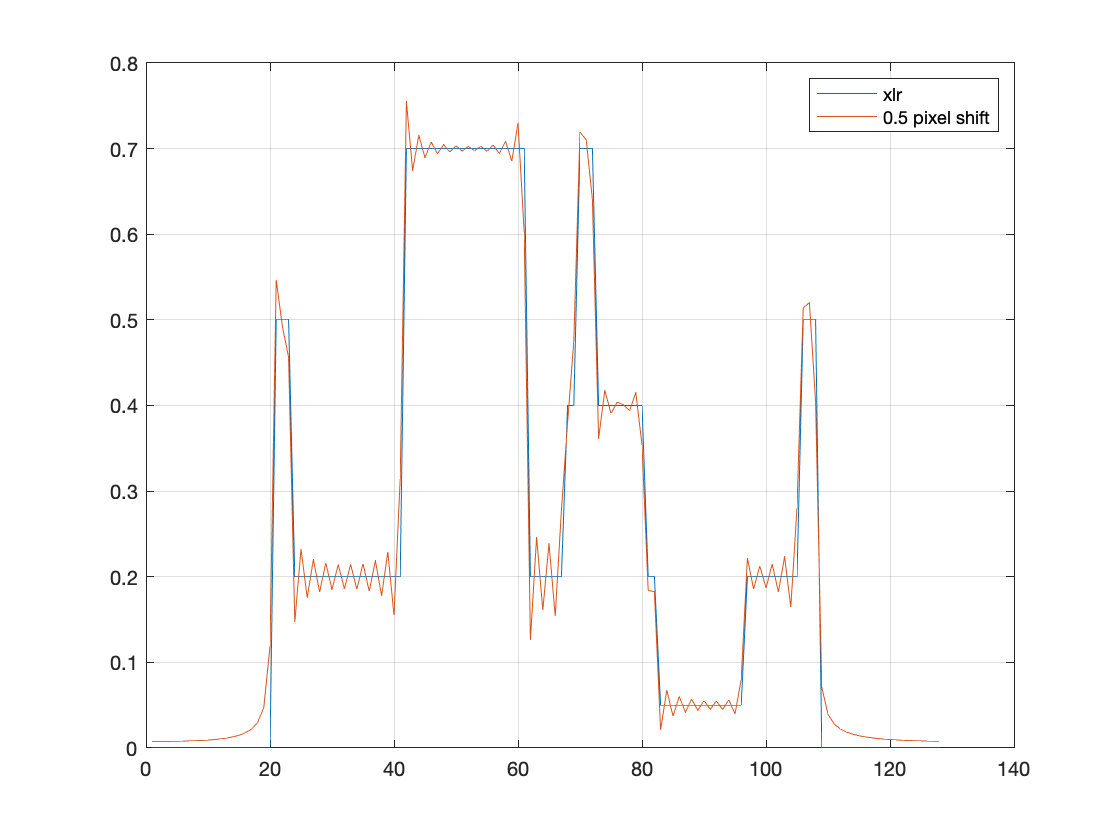

nlr = 128 ; column = 60 ;
imglr = prostate(nlr) ;
xlr = imglr(:,column) ;
klr = i2k(xlr) ;

figure
shift = 0.5 ;
phase_ramp = ( [1:nlr]'-sz2DC(nlr)) * shift * pi / nlr ;
plot(xlr, 'DisplayName', 'xlr'), legend, hold on, grid on
plot(abs(k2i(exp(1i*phase_ramp) .* klr)), 'DisplayName', '0.5 pixel shift')

This has implications for motion correction because if we apply phase ramps for various displacements, ringing comes and goes as the shift goes from fractional to integer pixel shifts. This could cause oscillations and false minima in a motion correction cost function. 

Ripples also manifest when performing B0 correction if the local B0 field results in a phase ramp.

### Summary

- Sharp edges in an image contain many spatial frequencies, decaying roughly as 1/k.

- TIme constraints mean we cannot measure all spatial frequenices.

- Truncation of spatial frequencies leads to Gibbs ringing in the image - an over and undershoot. In theory, the overshoot and undershoot are each always 9% of the step height. Increasing the resolution (acquiring more k-space)  narrows the ripples, but the overshoot remains at 9%.

- In practice, increasing resolution does seem to reduce the visual impact. Possible reasons for this may be:

-     The k-space decays to the level of noise as we go further out in k-space for higher spatial resolution.

-     Depending on the sequence and k-space ordering, the signal may be naturally low-pass filtered by T2 or other decay.

- Sampling an analog signal results in an aliasing from non-acquired spatial frequencies into those measured. An analogy is a rotating wheel viewed through a fence (repeated sampling). The wheel appears to rotate more slowly than reality.

- In the FE direction, the analog signal can be filtered to remove high frequences *before *sampling. In the PE direction, it is harder to think about as the signal comes with gaps. 